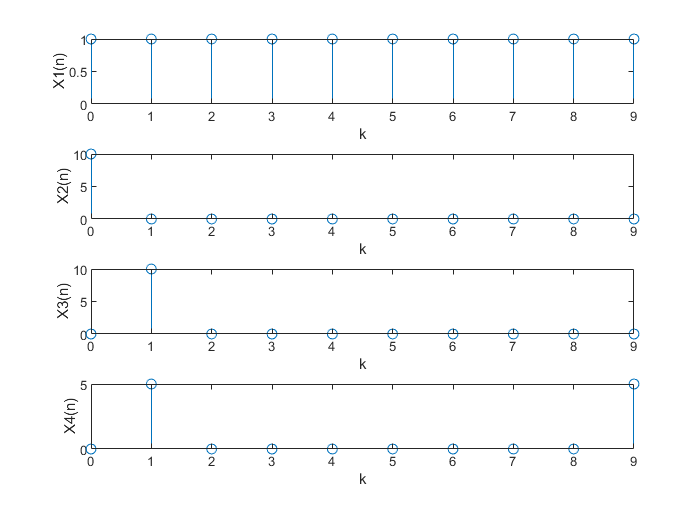

clear;close all;clc;
n=[0:9];
j=sqrt(-1);

x1=(n==0);
x2=ones(1:10);
x3=exp(j*2*pi*n/10);
x4=cos(2*pi*n/10);

figure(1);
hold on;
subplot(4,1,1);
X1=DFTsum(x1);
stem(n,abs(X1));xlabel('k');ylabel('X1(n)');
subplot(4,1,2);
X2=DFTsum(x2);
stem(n,abs(X2));xlabel('k');ylabel('X2(n)');
subplot(4,1,3);
X3=DFTsum(x3);
stem(n,abs(X3));xlabel('k');ylabel('X3(n)');
subplot(4,1,4);
X4=DFTsum(x4);
stem(n,abs(X4));xlabel('k');ylabel('X4(n)');

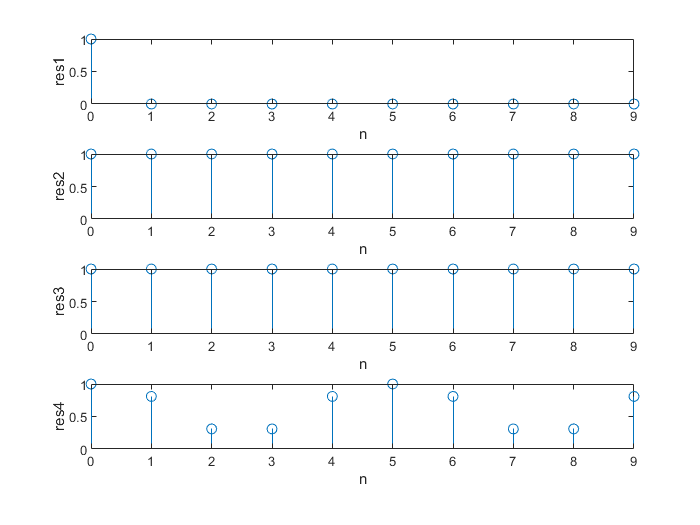

res1=IDFTsum(X1);
res2=IDFTsum(X2);
res3=IDFTsum(X3);
res4=IDFTsum(X4);
figure(2);
subplot(4,1,1);
stem(n,abs(res1));xlabel('n');ylabel('res1');
subplot(4,1,2);
stem(n,abs(res2));xlabel('n');ylabel('res2');
subplot(4,1,3);
stem(n,abs(res3));xlabel('n');ylabel('res3');
subplot(4,1,4);
stem(n,abs(res4));xlabel('n');ylabel('res4');